# Smoothing bathymetry

This guide shows how Matlab can be use to smooth bathymetry representations

## About

Smoothing bathymetry can be required in order to avoid artefacts in the representation that arise from procedures used to interpolate raw bathymetry data to the regular grid required for NewDepomod.

## Initialise and plot original bathymetry

We can start off with an initial bathymetry file.

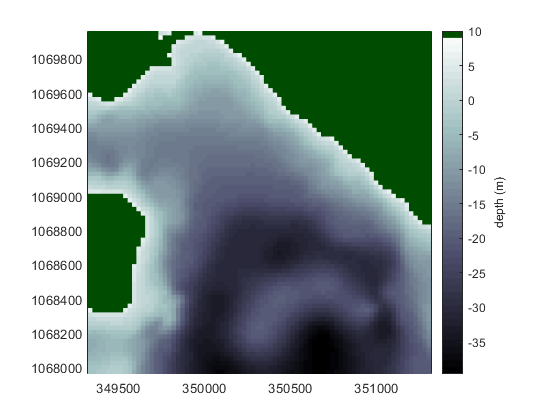

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = Depomod.Project.create(projectDir);
bathy      = project.bathymetry;

bathy.plot

## Smooth bathymetry

The bathymetry can be smoothed by invoking the following method

bathy.smoothSeabed

This causes water depth in the model domain to be averaged according to the neighbouring cells.

Typically, it might be necessary to run this a number of times

for s = 1:5
    project.bathymetry.smoothSeabed;
end

And we can check the results

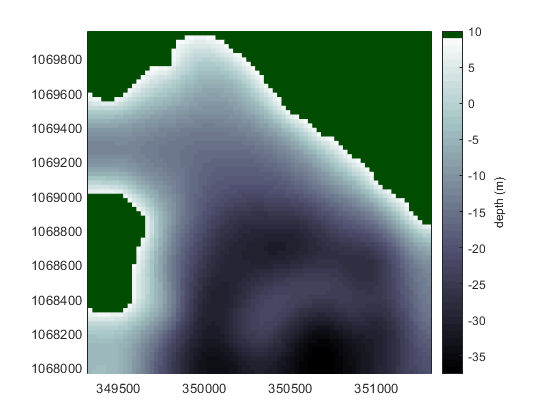

bathy.plot

## Saving the smoothed water depths

As usual, any changes can be saved back to file using

bathy.toFile